clear; close all;
%% load file from .mat
load datafile.mat % you can edit here if your datafile has a different name, but do not add path to the file (otherwise it does not work on a different computer)

% Enter code for question 2 here
%Guardamos las variables del fichero:
x1 = datafile.x1

x1 =     0.0219
    0.1692
    0.1946
   -0.0872
   -0.0482
   -0.0548
   -0.0601
   -0.1693
   -0.0932
   -0.0057


x2 = datafile.x2

x2 =     1.9700
    2.1700
    2.0500
    1.8000
    1.6200
    1.5300
    1.6800
    1.7200
    1.7500
    1.6500


y = datafile.y

y =         1744
        1675
        1649
        1589
        1598
        1594
        1630
        1744
        1746
        1721


%Creamos una matriz x, donde la primera columna son 1, la segunda columna
%los valores de x1 y la tercera columna los valores de x2.
A= ones(size(x1))

A =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


x = [A, x1, x2]

x =     1.0000    0.0219    1.9700
    1.0000    0.1692    2.1700
    1.0000    0.1946    2.0500
    1.0000   -0.0872    1.8000
    1.0000   -0.0482    1.6200
    1.0000   -0.0548    1.5300
    1.0000   -0.0601    1.6800
    1.0000   -0.1693    1.7200
    1.0000   -0.0932    1.7500
    1.0000   -0.0057    1.6500



%Calculamos su traspuesta:
xt = transpose(x)

xt =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0219    0.1692    0.1946   -0.0872   -0.0482   -0.0548   -0.0601   -0.1693   -0.0932   -0.0057   -0.1724    0.0844    0.1721    0.0503   -0.0242   -0.0194    0.2277    0.5464    0.4751    0.5408    0.4930    0.4896    0.4183    0.6806    0.5087    0.5805    0.7022    0.6269    0.6245    0.5910    0.6494    0.5809    0.7010    0.7133    0.3847    0.7099    0.5384    0.7517    0.4103    0.5339    0.5538    0.6671    0.5483    0.5125    0.5288    0.6662    0.6474    0.7345    0.5387    


%Multiplicamos la traspuesta por la matriz x:
xxt = xt*x

xxt =   120.0000   50.1177  244.5000
   50.1177   41.2718  127.7184
  244.5000  127.7184  541.8218



%Multiplicamos la traspuesta por y:
xty = xt*y

xty = 1.0e+05 *

    1.7136
    0.6215
    3.3613



%Calculamos la inversa de xxt:
inxxt = inv(xxt)

inxxt =     0.2170    0.1460   -0.1323
    0.1460    0.1879   -0.1102
   -0.1323   -0.1102    0.0875



%Calculamos el vector de los coeficientes independientes:
b=inxxt*xty

b = 1.0e+03 *

    1.7738
   -0.3363
   -0.1008


%Dibujamos el gráfico con los puntos de la matriz X
scatter3(x1,x2,y,'filled')
hold on
x1fit = min(x1):0.01:max(x1);
x2fit = min(x2):0.01:max(x2);
[X1FIT,X2FIT] = meshgrid(x1fit,x2fit);
YFIT = b(1) + X1FIT.*b(2) + X2FIT.*b(3)

YFIT = 1.0e+03 *

    1.8482    1.8449    1.8415    1.8381    1.8348    1.8314    1.8280    1.8247    1.8213    1.8180    1.8146    1.8112    1.8079    1.8045    1.8011    1.7978    1.7944    1.7911    1.7877    1.7843    1.7810    1.7776    1.7742    1.7709    1.7675    1.7642    1.7608    1.7574    1.7541    1.7507    1.7473    1.7440    1.7406    1.7372    1.7339    1.7305    1.7272    1.7238    1.7204    1.7171    1.7137    1.7103    1.7070    1.7036    1.7003    1.6969    1.6935    1.6902    1.6868    1.6834
    1.8472    1.8439    1.8405    1.8371    1.8338    1.8304    1.8270    1.8237    1.8203    1.8170    1.8136    1.8102    1.8069    1.8035    1.8001    1.7968    1.7934    1.7900    1.7867    1.7833    1.7800    1.7766    1.7732    1.7699    1.7665    1.7631    1.7598    1.7564    1.7531    1.7497    1.7463    1.7430    1.7396    1.7362    1.7329    1.7295    1.7262    1.7228    1.7194    1.7161    1.7127    1.7093    1.7060    1.7026    1.6992    1.6959    1.6925    1.6892 

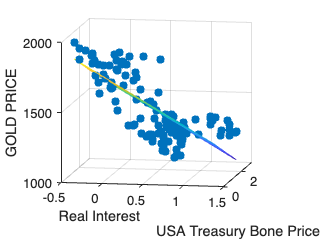

mesh(X1FIT,X2FIT,YFIT)
xlabel('Real Interest')
ylabel("USA Treasury Bone Price")
zlabel('GOLD PRICE')
view(10,10)
hold off


%%La relación entre el oro y los tipos de intereses, i el precio del bono va al revés. Cuando el tipo
%%de interes baja, entonces el precio del bono tambien baja, entonces los
%%inversores prefieren invertir en el oro, ya que les es más rentable. Sin
%%embargo, cuando estos dos ultimos suben, los inversores invierten en el
%%bono, por eso el precio del oro baja. 

% Calculamos y y la media:
yso = x * b;
media = mean(y, "all");

%Calculamos SSreg
res = (yso - media).^2;
SSreg = sum(res, 'all');

%Calculamos SStot
SStot = (y - media).^2;
SStot = sum(SStot, 'all');

%Calculamos SSerr
SSerr = SStot - SSreg;

%Grados de libertad
k = 2;
n1=size(y)

n1 =    120     1


n = n1(1)

n = 120


%Calculamos MSreg
MSreg = SSreg/k;

%Calculamos MWerr
MSerr = SSerr/(n-k-1)

MSerr = 2.1546e+04


%Calculamos F estadístico
F=MSreg/MSerr

F = 103.9560


%Calculamos la F 
f=finv(0.95, k, n-k-1);

%Calculamos su p-value
pf = 1-fcdf(F,2,n-k-1);

%Calculamos R^2
cdet = SSreg/SStot; %Esto es la R^2


%%CONCLUSIONES:
%%En este caso, se puede observar, como el modelo explica el 63% de la
%%variabilidad de la variable independiente. Al realizar el test de
%%significación del modelo, el estadístico F ha dado como resultado
%%103.9560, lo cual ya nos da una pista de que seguramente se rechazará la
%%hipótesis nula. Sin embargo, para confirmarlo se ha calculado el F con el
%%que se compara y nos ha dado 3.078, además de que el pvalue ha dado 0.
%%Con lo cual, se rechaza la hipótesis nula con toda la seguredad. El
%%modelo contiene al menos algún coeficiente x1 y x2 que són diferentes a
%%0, es decir, son significativos para el modelo.

%Calculamos la matriz de varianzas y covarianzas
vcov = MSerr*inv(xxt)

vcov = 1.0e+03 *

    4.6748    3.1467   -2.8513
    3.1467    4.0477   -2.3741
   -2.8513   -2.3741    1.8860



%Hacemos el estudio para b1 que es para la x1:
sb1= vcov(2,2)

sb1 = 4.0477e+03

tb1 = b(2)/sqrt(sb1) %estadístico 

tb1 = -5.2860

t1 = tinv(0.95, n-1) %t para comparar con alfa 0.05

t1 = 1.6578

%Calculamos el p value
pt1 = 1-tcdf(abs(tb1), n-1)

pt1 = 2.8741e-07


%Hacemos el estudio para b2 que es para la x2:
sb2 = vcov(3,3)

sb2 = 1.8860e+03

tb2 = b(3)/sqrt(sb2) %estadístico 

tb2 = -2.3209

t2=tinv(0.95, n-1) %t para comparar con alfa 0.05

t2 = 1.6578

%Calculem el p value
pt2 = 1-tcdf(abs(tb2), n1-1)

pt2 =     0.0110       NaN




%%CONCLUSIONES:

%PARA X1:
%Para la b1, el estadístico (tb1) ha dado -5.2860, y la t1 para comparar ha
%dado 1.6578. Como que tb1 < t1, se rechaza la hipótesis nula. Por
%lo cual, el beta 1 es significativo, y por ello, el valor del tipo de
%interés real influye sobre el precio final del oro. El p-value ya nos
%confirma eso, ya que nos da un valor de 0.000028741, que es menor a
%cualquier alfa de la tabla de t student. Por tanto, independientemente del
%valor del alfa la b1 es significativa para el modelo.

%PARA X2:
%Para la b2, el estadístico (tb2) ha dado -2.3209, y la t student con alfa
%0.05 ha dado 1.6578. Como que tb1 < t2, también se rechaza la hipótesis
%nula. Por o cual, el beta 2 es significativo, y por ello, el valor de la
%rentabilidad del oro influye sobre el precio final del oro. El p-value ha dado 0.0110, si
%lo comparamos con el alfa 0.05, al ser menor al alfa, confirma el rechazo
%de la hipótesis nula. 